# Classifying Brain States from EEG-Data

Welcome to this demonstration on using machine learning to classify brain states from EEG data!

We will be using publicly available EEG data obtained with the Backyard Brains Heart and Brain Spiker Box. The data was collected from volunteer users engaged in an eyes open/eyes closed task. Our goal is to use this data to construct a classifer which can take new EEG data and accurately determine whether the subject has their eyes open or their eyes closed during the recording. We will follow this basic machine-learning workflow:

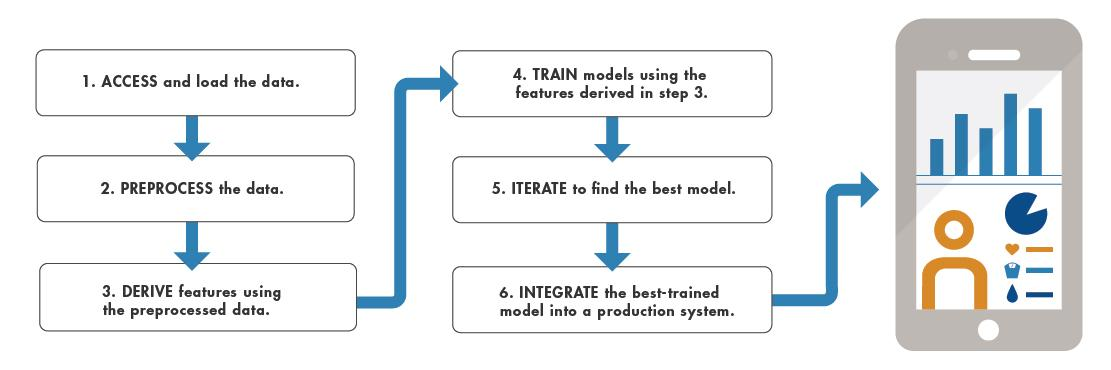

## Download and Reshape EEG Data

The helper function [loadEEGdata](matlab:open('.\+helper\loadEEGdata.mlx')) downloads recordings taken with Backyard Brains Spike Recorder App. The data format is .wav sound files containing the signal data, and .txt files that contain the annotations of what times correspond to eyes open vs. eyes closed. We use the helper function [reshapeEEGdata](matlab:open('./+helper\reshapeEEGdata.mlx')) to combine the data from all the different experiments into a single variable in a format that we can then further process so that it is suitable to train a classifier on. The result of running the above livescript is a .mat file containing the data from our experiments.

**You need to run this section only once!** If you have done so before, the files (especially the EEG_data.mat file) should be in the data subfolder.

helper.downloadEEGdata;
[signalData, responseData] = helper.reshapeEEGdata;

## Visualize the data

Let's quickly visualize the imported data to make sure that everything so far matches our expectations. This code plots one of our datafiles. Here we simply loop through each label class and plot all the relevant indices that match that label.

signal = signalData{1}(1,:);

Error using websave
Unable to open output file: 'data/BYB_Recording_2021-08-25_14.34.23-events.txt' for writing. Common reasons include that the file exists and does not have write permission or the folder does not have write permissions.

Error in helper.downloadEEGdata (line 12)
    websave(targetFN, files2Load(thisfile).download_url);

label = responseData{1};
sampleN = 1:numel(signal);

figure
plot(sampleN(label=="3"),signal(label=="3"));
hold on
plot(sampleN(label=="4"),signal(label=="4"));

legend({"eyes open", "eyes closed"})
xlabel("Time [ms]")
ylabel("Voltage")
title("Ground Truth Labels: Eyes Open vs. Closed")
clear variables

## Classify Eyes Open Vs. Closed

In this livescript, we build a classifier model to classify whether a subject's eyes are open or closed based on the existence of alpha waves in the EEG dataset. Over the course of several experiments, individuals were tasked with holding their eyes open and closed for several seconds at a time in each state. This labeled dataset allows us to build a classifier that can, given new data, determine at what time points the subject has/had their eyes open and at what points are/were their eyes closed.

In EEG data, the distinction between eyes open and closed is most directly observed through the existence of alpha waves. [Alpha waves](https://en.wikipedia.org/wiki/Alpha_wave) occur most prominently during wakeful relaxation with closed eyes. 

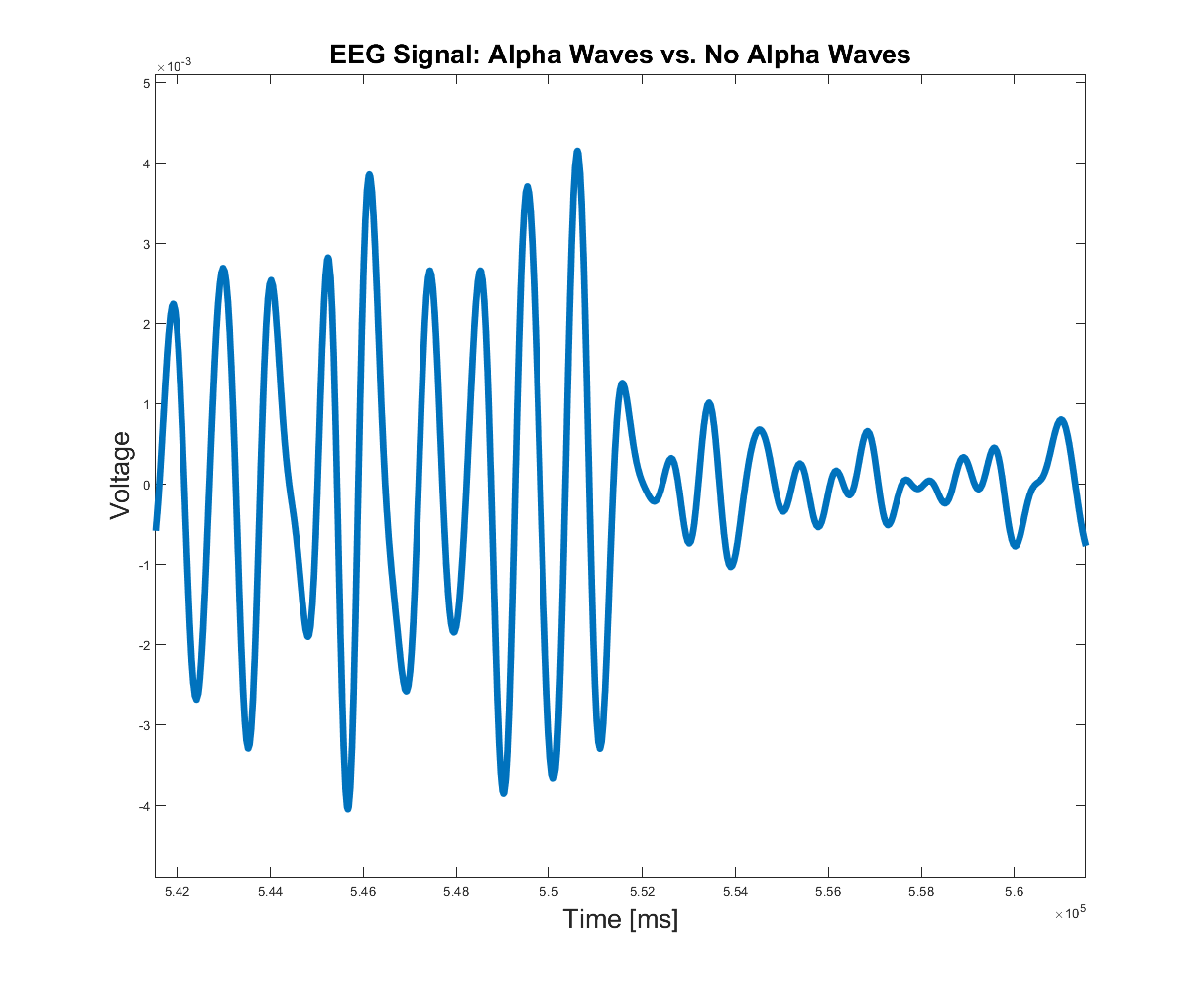

This figure illustrates a time period when the eyes are closed during the first half of the plot, and open during the second. The entire signal was imported with a bandpass filter around the 5-15 Hz range, where alpha waves are [most likely be be found](https://www.sciencedirect.com/topics/medicine-and-dentistry/alpha-wave). We can clearly see that during periods of eyes closed, there is a much stronger signal within this frequency range compared to when the eyes are open. 

### Load Data

Let's load the data that we have stored in "EEG_data.mat". This .mat file contains two variables: signalData and responseData. The "signalData" variable is a cell array that stores the signal data (a number for each time point) for one experiment in each cell. The "responseData" is a cell array that contains the labels corresponding to the matching experiment in "signalData"

load("data/EEG_data.mat");

### Preprocess the Data

The preprocessing and feature extraction steps occur in [**preprocessEEGdata**](matlab:open('./+helper\preprocessEEGdata.mlx')). There the following common preprocessing steps occur:

- Filtering the data in the frequency domain

- Truncating, reshaping and combing the data from different experiments

- Match labels to reshaped data

- Extract features for classification from the raw data (here the frequency spectrum of 1s chunks of our EEG data are used as feature for classification)

Make sure to check out the live-function to get a better idea of each step, the function is well documented with text and images!

[signalDataSplitted, labelsEachSecond] = helper.preprocessEEGdata(signalData, responseData);

### (Optional) Explore Machine Learning Models visually with the Classification-Learner App

At this stage in the analysis it could be that we have no good idea how to classify the data and need some explorative work. For this use-case, the Classification-Learner App was designed! It will graphically allow you to explore and evaluate different classes of machine-learning models againsts your data.

If you want to experience this typical explorative step in machine learning workflows, please check out [**this live-script**](matlab:open('.\exploreMachineLearningModels.mlx')).

### Divide Data into a Training- and a Test-Dataset

A common step in Machine Learning workflows is to reserve parts of the dataset under study for testing, so that these particular data are "new" to the algorithm. Performance of the model is then tested against these "unknown" data.

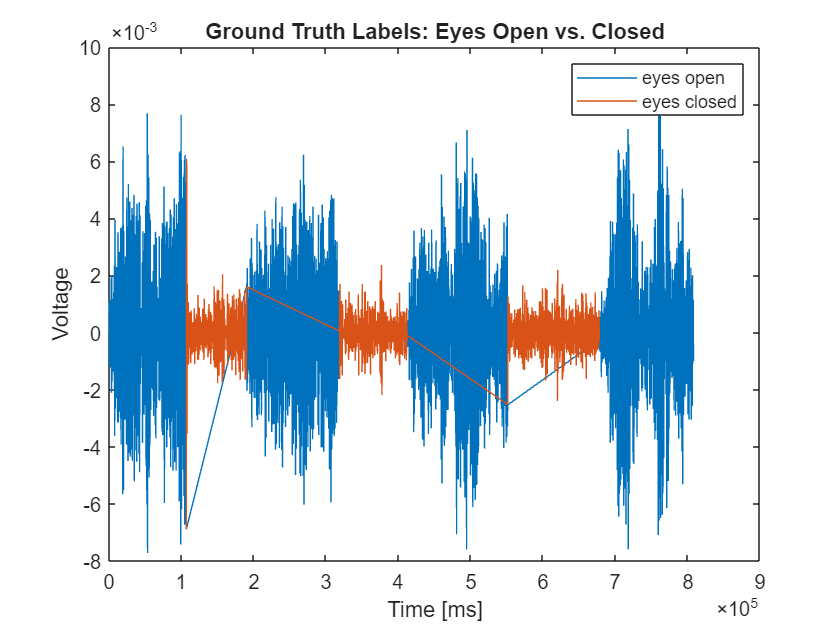

signalDataTraining = signalDataSplitted(1:1200,:);
labelsTraining = labelsEachSecond(1:1200,:);

signalDataTesting = signalDataSplitted(1201:end,:);
labelsTesting = labelsEachSecond(1201:end,:);

### Create a Classification Model

For now we assume we know which particular model suits our problem and dataset. If we want to create such a model quickly and in a reproducible way it is often easiest to create it programmatically.

We assume that the "k-nearest classification model" explained in this [**this live-script**](matlab:open('.\exploreMachineLearningModels.mlx')) is best for us. The ["fitcknn"](https://www.mathworks.com/help/stats/fitcknn.html) function provides a simple way for creating k-nearest classification models in MATLAB:

Mdl = fitcknn(signalDataTraining, labelsTraining,'NumNeighbors',13);

Which creates a k-nearest neighbor model using the time chunks selected as training data (roughly 70% of all the data that we have), and stores that model in the "Mdl" variable.

### Test the Performance of Our Classification Model 

Having created our model object, using it to make classifications on "new" data (the 30% of the data that we did not use to create our model) is relatively simple. Let's now test our model on the dataset. 

predictions = [];
for idx = 1:height(labelsTesting)
    predictedLabel = predict(Mdl, signalDataTesting(idx,:));
    labelsPredict(idx) = double(predictedLabel);
end

Here we simply use the ["predict" method](https://www.mathworks.com/help/stats/classificationknn.predict.html) in MATLAB in a for loop, which takes in a model object (our "Mdl") and the data that we want to classify (the frequency info of one chunk of time) and gives us the label that it believes best classifies it.

Let us compare the ground-truth to the prediction now. We will rename the true and predicted categories into "opened" and "closed", for easier reading. Then we will plot a confusion matrix:

labelsTestingNamed = categorical(labelsTesting,categorical([3,4]),{'opened','closed'});
labelsPredictNamed = categorical(labelsPredict,[1,2],{'opened','closed'})';
figure()
confusionchart(labelsTestingNamed,labelsPredictNamed,"Title","Confusion Matrix For Classification of EEG data")

As well as calculate the accuracy (simply counting all the correct predictions and dividing by the total number of chunks we tried to predict):

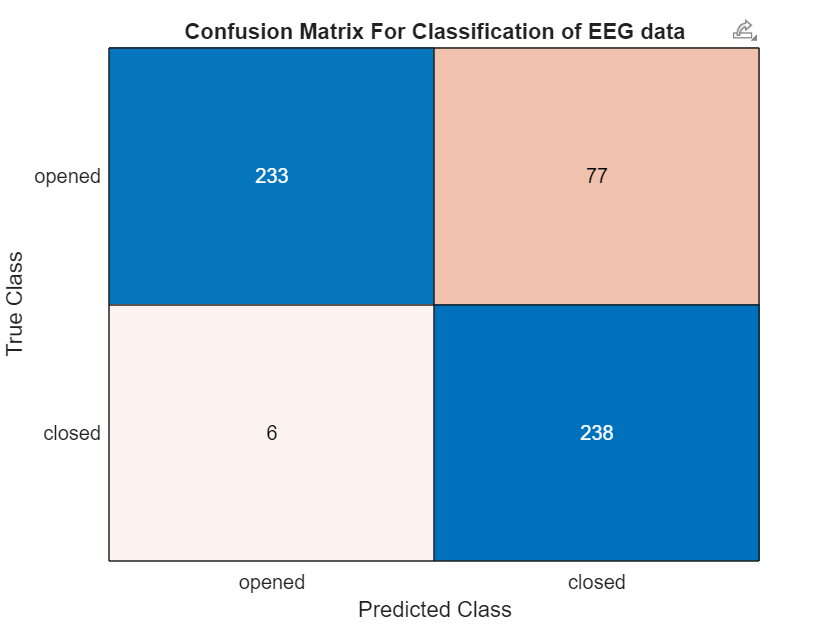

85% of all EEG segments were classified correctly


correctLabel = labelsTestingNamed == labelsPredictNamed;
disp(num2str((sum(correctLabel) / numel(correctLabel))*100,2) + "% of all EEG segments were classified correctly")

As we can see, this naive method produces a model that performs pretty well already. This would be a good starting point to further tweak and optimize the classifier model.

## Go further

For more background information on EEGs, please refer to [https://backyardbrains.com/experiments/eeg.](https://backyardbrains.com/experiments/eeg.) 

© 2023 The MathWorks, Inc.